In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

% Define arm base curve
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
g_tip = poses(:, :, end);

q = zeros(3, N_poses);
for i = 1 : N_poses
    g_i = poses(:, :, i);
    g_i_tip = inv(g_i) * g_tip;
    g_ucirc_right_tip = Pose2.left_lifted_action(g_tip)' * Q_tip;
    g_ucirc_right_s = inv(Pose2.adjoint(g_i_tip))' * g_ucirc_right_tip;

    q(:, i) = g_ucirc_right_s;
end
figure("position", [0, 0, 1500, 500]);

subplot(1, 2, 1)
hold on
plot(s, q(1, :));
plot(s, q(3, :));
legend("Linear force", "Bending moment", "location", "southeast")

subplot(1, 2, 2)
plot(q(1, :), q(3, :))
xlabel("q_f [N]")
ylabel("q_m [Nm]")

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

p = [15; 0; 15; 0]; %kPa

% Define actuator forces
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];

% Compute the strains of each rods
l_0 = 0.5;
strain_o = (l - l_0) / l_0;

mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

lengths = zeros(4, N_poses);
strains = zeros(4, N_poses);
forces = zeros(4, N_poses);
for i = 1 : length(rhos)
    lengths(i, :) = segment_twists(1, :) - rhos(i) * segment_twists(3, :);
    strains(i, :) = (lengths(i, :) - l_0) / l_0;
    for j = 1 : length(forces)
        forces(i, j) = fs{i}(strains(i, j), p(i));
    end
end

reaction_forces = mat_A * forces;
figure()
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0")
grid on

struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

f_residual = @(mat_segment_twists) f_check_equilibrium(mat_segment_twists, Q_tip, p, struct_design);

tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;

opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt");
[soln, res, ~, output] = fsolve(f_residual, default_segment_twists, opts);


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>


disp(res)

  -0.001807415647091  -0.002662349353072  -0.005039038449619  -0.008905564729600  -0.014095316207609  -0.020379000177043  -0.027462336070029  -0.035138298026423  -0.043295362742112  -0.053558420762785
   0.000001274338804   0.000003012765466   0.000005851127556   0.000009827607703   0.000014133977503   0.000017186516398   0.000016785331896   0.000010156752410  -0.000006155793259  -0.000036434890620
   0.128338502896538   0.188287506820312   0.354631500815320   0.624556419945025   0.985914836308743   1.423220882696104   1.910600444731072   2.422556256213664   2.940150285748968   3.446152840255009



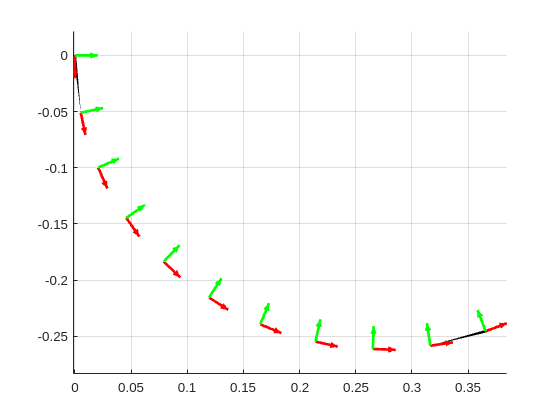


poses = calc_poses(g_0, soln);
ax = axes(figure());
plot_poses(poses, ax);
grid on

toc

Elapsed time is 0.923129 seconds.


% Construct a similar arm but using the previous library to check for
% equivalence
tic
arm = ArmSeriesFactory.constant_2d_antagonist_arm(N_poses, rho_inner, rho_outer, l_0);
arm.set_mechanics(JacobBellowMechanics(l_0), [1, 4]);
arm.solve_equilibrium_gina(p, Q_tip, print=true);


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>
fzero residual is nonzero (> 0.01). Printing: 
  -0.001807637519356  -0.002662525963920  -0.005039164184167  -0.008905598382331  -0.014095236958340  -0.020378832302015  -0.027462072800679  -0.035137816396005  -0.043294170094716  -0.054196501837198
   0.000012744904149   0.000030130515360   0.000058515528808   0.000098282754980   0.000141350952807   0.0001718839839

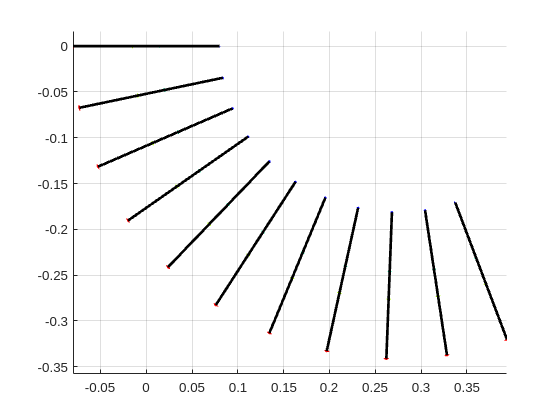

Plotter2D.plot_arm_series(arm, axes(figure()))

toc

Elapsed time is 28.723102 seconds.


function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function poses = calc_poses(g_0, mat_segment_twists)
    N_twists = size(mat_segment_twists, 2);
    ds = 1/N_twists;
    N_poses = N_twists + 1;

    poses = zeros(3, 3, N_poses);
    poses(:, :, 1) = g_0;
    for i = 1 : N_twists

        % Get the current twist
        segment_twist_s = mat_segment_twists(:, i);

        % Compute the next displacement
        delta_g = Twist2.expm(segment_twist_s*ds);

        % Apply the next displacement
        poses(:, :, i+1) = poses(:, :, i) * delta_g;
    end
end

function plot_poses(poses, ax, linestyle)

    arguments
        poses
        ax
        linestyle="k-";
    end

    axis_length = 0.15;

    % Extract position components
    p_x = squeeze(poses(1, 3, :));
    p_y = squeeze(poses(2, 3, :));

    % Extract x unit vector components
    x_u = squeeze(poses(1, 1, :));
    x_v = squeeze(poses(2, 1, :));

    y_u = squeeze(poses(1, 2, :));
    y_v = squeeze(poses(2, 2, :));

    % Plot
    hold(ax, "on")
    plot(ax, p_x, p_y, linestyle, "linewidth", 2);
    quiver(ax, p_x, p_y, x_u, x_v, axis_length, "red", "linewidth", 2);
    quiver(ax, p_x, p_y, y_u, y_v, axis_length, "green", "linewidth", 2);
    axis(ax, "equal")
end

function reaction_wrenches = f_calc_reaction_wrench(mat_segment_twists, p, struct_design)
    N_twists = size(mat_segment_twists, 2);
    lengths_o = mat_segment_twists(1, :);
    
    lengths = zeros(4, N_twists);
    strains = zeros(4, N_twists);
    forces = zeros(4, N_twists);
    for i = 1 : length(struct_design.rhos)
        lengths(i, :) = lengths_o - struct_design.rhos(i) * mat_segment_twists(3, :);
        strains(i, :) = (lengths(i, :) - struct_design.l_0) / struct_design.l_0;
        for j = 1 : length(strains)
            forces(i, j) = struct_design.fs{i}(strains(i, j), p(i));
        end
    end
    reaction_wrenches = struct_design.mat_A * forces;
end

function external_wrenches = f_calc_external_wrench(mat_segment_twists, Q_tip, struct_design)
    N_twists = size(mat_segment_twists, 2);
    poses = calc_poses(struct_design.g_0, mat_segment_twists);
    g_tip = poses(:, :, end);
    
    external_wrenches = zeros(3, N_twists);
    for i = 1 : N_twists
        g_i = poses(:, :, i);
        g_i_tip = inv(g_i) * g_tip;
        
        % Convert the world frame tip force to be in the rod tip's frame
        g_ucirc_right_tip = Pose2.left_lifted_action(g_tip)' * Q_tip;

        % Since the force is now in the rod's "material-centric" frame,
        % we can therefore use the adjoint to find its contribution on an
        % earlier part of the rod.
        g_ucirc_right_s = inv(Pose2.adjoint(g_i_tip))' * g_ucirc_right_tip;
    
        external_wrenches(:, i) = g_ucirc_right_s;
    end
end

function residual = f_check_equilibrium(mat_segment_twists, Q_tip, p, struct_design)
    % Compute the externally applied wrenches
    external_wrenches = f_calc_external_wrench(mat_segment_twists, Q_tip, struct_design);

    % Compute the internal reaction wrenches
    reaction_wrenches = f_calc_reaction_wrench(mat_segment_twists, p, struct_design);

    residual = external_wrenches + reaction_wrenches;
    residual(2, :) = 1e5 * mat_segment_twists(2, :);
end